## **Internal Cross Validation of Multiple Linear Regression Model - Replication Sample (AOMIC) **

## **Part 1 - Internal Cross Validation of Multiple Linear Regression Model **

This  is Part 1 of the Internal Cross Validation of the Multiple Linear Regression Model. It partitions the sample into 5 different folds and creates the positive and negative NMAs for each training fold and test fold based on the correllation with cognitive ability scores

Before Running this script:

- run AOMIC_compute_coupling_measures 

**1) Create a cell that contains for each subject a vector of 8 predictors for each node **

for i = 1:567
    x = final_r_all_AOMIC_567_new{i,1};
    for j = 1:358
    Node_all_baseline_AOMIC_weighted_only{i,j} = x(j,:);
    end
end


**2) Create cell that contains information from all subjects and all coupling measures for all nodes separetely (567*8)**

% extract for each collumn die 8 rows from each row and put them together in a matrix (--> I need 568*8 Matrix for each Node)

n = size(Node_all_baseline_AOMIC_weighted_only,2);
All_Nodes_complete_baseline_AOMIC_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_AOMIC_weighted_only{j} = vertcat(Node_all_baseline_AOMIC_weighted_only{:,j});
end 


2.1.) Fix Problems with Node 171 & Node 343

Convert all Isnan Values to 0 (so that the Code works) 

% Node 38 
all_values_171 = All_Nodes_complete_baseline_AOMIC_weighted_only{1,171};
all_values_171(isnan(all_values_171)) = 0;

All_Nodes_complete_baseline_AOMIC_weighted_only{1,171} = all_values_171;


% Node 58 
all_values_343 = All_Nodes_complete_baseline_AOMIC_weighted_only{1,343};
all_values_343(isnan(all_values_343)) = 0;

All_Nodes_complete_baseline_AOMIC_weighted_only{1,343} = all_values_343;


**3) Split into 5 folds **

**Create a Loop to Do the Partition 100 times **

for cross_validation_round = 1:100;
    display(cross_validation_round)

3.1) Create Random Test and Training Samples 

Intelligence = AOMIC_behavioral_567_numerical.IST_intelligence_total;


Intelligence_for_cv_partition_1 = rescale(Intelligence,1,30);
Intelligence_for_cv_partition = int16(Intelligence_for_cv_partition_1); % create 30 groups to ultimatly create a startified cv partition

c = cvpartition(Intelligence_for_cv_partition,'KFold',5);

cross_validation_round = 1

cross_validation_round = 2

cross_validation_round = 3

cross_validation_round = 4

cross_validation_round = 5

cross_validation_round = 6

cross_validation_round = 7

cross_validation_round = 8

cross_validation_round = 9

cross_validation_round = 10

cross_validation_round = 11

cross_validation_round = 12

cross_validation_round = 13

cross_validation_round = 14

cross_validation_round = 15

cross_validation_round = 16

cross_validation_round = 17

cross_validation_round = 18

cross_validation_round = 19

cross_validation_round = 20

cross_validation_round = 21

cross_validation_round = 22

cross_validation_round = 23

cross_validation_round = 24

cross_validation_round = 25

cross_validation_round = 26

cross_validation_round = 27

cross_validation_round = 28

cross_validation_round = 29

cross_validation_round = 30

cross_validation_round = 31

cross_validation_round = 32

cross_validation_round = 33

cross_validation_round = 34

cross_validation_round = 35

cross_validation_round = 36

cross_validation_round = 37

cross_validation_round = 38

cross_validation_round = 39

cross_validation_round = 40

cross_validation_round = 41

cross_validation_round = 42

cross_validation_round = 43

cross_validation_round = 44

cross_validation_round = 45

cross_validation_round = 46

cross_validation_round = 47

cross_validation_round = 48

cross_validation_round = 49

cross_validation_round = 50

cross_validation_round = 51

cross_validation_round = 52

cross_validation_round = 53

cross_validation_round = 54

cross_validation_round = 55

cross_validation_round = 56

cross_validation_round = 57

cross_validation_round = 58

cross_validation_round = 59

cross_validation_round = 60

cross_validation_round = 61

cross_validation_round = 62

cross_validation_round = 63

cross_validation_round = 64

cross_validation_round = 65

cross_validation_round = 66

cross_validation_round = 67

cross_validation_round = 68

cross_validation_round = 69

cross_validation_round = 70

cross_validation_round = 71

cross_validation_round = 72

cross_validation_round = 73

cross_validation_round = 74

cross_validation_round = 75

cross_validation_round = 76

cross_validation_round = 77

cross_validation_round = 78

cross_validation_round = 79

cross_validation_round = 80

cross_validation_round = 81

cross_validation_round = 82

cross_validation_round = 83

cross_validation_round = 84

cross_validation_round = 85

cross_validation_round = 86

cross_validation_round = 87

cross_validation_round = 88

cross_validation_round = 89

cross_validation_round = 90

cross_validation_round = 91

cross_validation_round = 92

cross_validation_round = 93

cross_validation_round = 94

cross_validation_round = 95

cross_validation_round = 96

cross_validation_round = 97

cross_validation_round = 98

cross_validation_round = 99

cross_validation_round = 100

3.2) Assign the Indices to the randomly created Test and Training Samples

Train 1 & Test 1 

index_test_1 = find(test(c,1));
index_train_1 = find(training(c,1));


Train 2 & Test 2 

index_test_2 = find(test(c,2));
index_train_2 = find(training(c,2));

Train 3 & Test 3 

index_test_3 = find(test(c,3));
index_train_3 = find(training(c,3));

Train 4 & Test 4 

index_test_4 = find(test(c,4));
index_train_4 = find(training(c,4));

Train 5 & Test 5 

index_test_5 = find(test(c,5));
index_train_5 = find(training(c,5));

**4) Divide Data in Test and Training Samples **

4.1)  Divide the coupling data into 5 Training and 5 Test Samples

for i = 1:358
   all_data_node = All_Nodes_complete_baseline_AOMIC_weighted_only{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1,:);
   Node_test_sample_1 = all_data_node(index_test_1,:);
   
   Node_training_sample_2 = all_data_node(index_train_2,:);
   Node_test_sample_2 = all_data_node(index_test_2,:);
   
   Node_training_sample_3 = all_data_node(index_train_3,:);
   Node_test_sample_3 = all_data_node(index_test_3, :);
   
   Node_training_sample_4 = all_data_node(index_train_4,:);
   Node_test_sample_4 = all_data_node(index_test_4,:);
   
   Node_training_sample_5 = all_data_node(index_train_5,:);
   Node_test_sample_5 = all_data_node(index_test_5, :);
   
   All_Nodes_complete_cross_validation_AOMIC_weighted_only{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_AOMIC_weighted_only{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_AOMIC_weighted_only{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_AOMIC_weighted_only{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_AOMIC_weighted_only{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_AOMIC_weighted_only{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_AOMIC_weighted_only{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_AOMIC_weighted_only{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_AOMIC_weighted_only{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_AOMIC_weighted_only{10,i} = Node_test_sample_5;
   
end

4.2) Divide Intelligence into 5 Training Samples & 5 Test Samples

Intelligence = AOMIC_behavioral_567_numerical.IST_intelligence_total;

Intelligence_train_1 = Intelligence(index_train_1,:);
Intelligence_train_2 = Intelligence(index_train_2,:);
Intelligence_train_3 = Intelligence(index_train_3,:);
Intelligence_train_4 = Intelligence(index_train_4,:);
Intelligence_train_5 = Intelligence(index_train_5,:);

Intelligence_test_1 = Intelligence(index_test_1,:);
Intelligence_test_2 = Intelligence(index_test_2,:);
Intelligence_test_3 = Intelligence(index_test_3, :);
Intelligence_test_4 = Intelligence(index_test_4,:);
Intelligence_test_5 = Intelligence(index_test_5, :);


Intelligence_training_samples{1,:} = Intelligence_train_1;
Intelligence_training_samples{2,:} = Intelligence_train_2;
Intelligence_training_samples{3,:} = Intelligence_train_3;
Intelligence_training_samples{4,:} = Intelligence_train_4;
Intelligence_training_samples{5,:} = Intelligence_train_5;

Intelligence_test_samples{1,:} = Intelligence_test_1;
Intelligence_test_samples{2,:} = Intelligence_test_2;
Intelligence_test_samples{3,:} = Intelligence_test_3;
Intelligence_test_samples{4,:} = Intelligence_test_4;
Intelligence_test_samples{5,:} = Intelligence_test_5;

4.3)  Divide Confounding Variables into 5 Training Samples & 5 Test Samples

ALter = AOMIC_behavioral_567_numerical.age;

ALter_train_1 = ALter(index_train_1,:);
ALter_train_2 = ALter(index_train_2,:);
ALter_train_3 = ALter(index_train_3,:);
ALter_train_4 = ALter(index_train_4,:);
ALter_train_5 = ALter(index_train_5,:);

ALter_test_1 = ALter(index_test_1,:);
ALter_test_2 = ALter(index_test_2,:);
ALter_test_3 = ALter(index_test_3, :);
ALter_test_4 = ALter(index_test_4,:);
ALter_test_5 = ALter(index_test_5, :);

ALter_training_samples{1,:} = ALter_train_1;
ALter_training_samples{2,:} = ALter_train_2;
ALter_training_samples{3,:} = ALter_train_3;
ALter_training_samples{4,:} = ALter_train_4;
ALter_training_samples{5,:} = ALter_train_5;

ALter_test_samples{1,:} = ALter_test_1;
ALter_test_samples{2,:} = ALter_test_2;
ALter_test_samples{3,:} = ALter_test_3;
ALter_test_samples{4,:} = ALter_test_4;
ALter_test_samples{5,:} = ALter_test_5;


Gender = AOMIC_behavioral_567_numerical.sex_num;

Gender_train_1 = Gender(index_train_1,:);
Gender_train_2 = Gender(index_train_2,:);
Gender_train_3 = Gender(index_train_3,:);
Gender_train_4 = Gender(index_train_4,:);
Gender_train_5 = Gender(index_train_5,:);

Gender_test_1 = Gender(index_test_1,:);
Gender_test_2 = Gender(index_test_2,:);
Gender_test_3 = Gender(index_test_3, :);
Gender_test_4 = Gender(index_test_4,:);
Gender_test_5 = Gender(index_test_5, :);

Gender_training_samples{1,:} = Gender_train_1;
Gender_training_samples{2,:} = Gender_train_2;
Gender_training_samples{3,:} = Gender_train_3;
Gender_training_samples{4,:} = Gender_train_4;
Gender_training_samples{5,:} = Gender_train_5;

Gender_test_samples{1,:} = Gender_test_1;
Gender_test_samples{2,:} = Gender_test_2;
Gender_test_samples{3,:} = Gender_test_3;
Gender_test_samples{4,:} = Gender_test_4;
Gender_test_samples{5,:} = Gender_test_5;

meanFDJenk = AOMIC_behavioral_567_numerical.("Mean FD");

meanFDJenk_train_1 = meanFDJenk(index_train_1,:);
meanFDJenk_train_2 = meanFDJenk(index_train_2,:);
meanFDJenk_train_3 = meanFDJenk(index_train_3,:);
meanFDJenk_train_4 = meanFDJenk(index_train_4,:);
meanFDJenk_train_5 = meanFDJenk(index_train_5,:);

meanFDJenk_test_1 = meanFDJenk(index_test_1,:);
meanFDJenk_test_2 = meanFDJenk(index_test_2,:);
meanFDJenk_test_3 = meanFDJenk(index_test_3, :);
meanFDJenk_test_4 = meanFDJenk(index_test_4,:);
meanFDJenk_test_5 = meanFDJenk(index_test_5, :);


meanFDJenk_training_samples{1,:} = meanFDJenk_train_1;
meanFDJenk_training_samples{2,:} = meanFDJenk_train_2;
meanFDJenk_training_samples{3,:} = meanFDJenk_train_3;
meanFDJenk_training_samples{4,:} = meanFDJenk_train_4;
meanFDJenk_training_samples{5,:} = meanFDJenk_train_5;

meanFDJenk_test_samples{1,:} = meanFDJenk_test_1;
meanFDJenk_test_samples{2,:} = meanFDJenk_test_2;
meanFDJenk_test_samples{3,:} = meanFDJenk_test_3;
meanFDJenk_test_samples{4,:} = meanFDJenk_test_4;
meanFDJenk_test_samples{5,:} = meanFDJenk_test_5;


LQ = AOMIC_behavioral_567_numerical.handedness_num;

LQ_train_1 = LQ(index_train_1,:);
LQ_train_2 = LQ(index_train_2,:);
LQ_train_3 = LQ(index_train_3,:);
LQ_train_4 = LQ(index_train_4,:);
LQ_train_5 = LQ(index_train_5,:);

LQ_test_1 = LQ(index_test_1,:);
LQ_test_2 = LQ(index_test_2,:);
LQ_test_3 = LQ(index_test_3, :);
LQ_test_4 = LQ(index_test_4,:);
LQ_test_5 = LQ(index_test_5, :);


LQ_training_samples{1,:} = LQ_train_1;
LQ_training_samples{2,:} = LQ_train_2;
LQ_training_samples{3,:} = LQ_train_3;
LQ_training_samples{4,:} = LQ_train_4;
LQ_training_samples{5,:} = LQ_train_5;

LQ_test_samples{1,:} = LQ_test_1;
LQ_test_samples{2,:} = LQ_test_2;
LQ_test_samples{3,:} = LQ_test_3;
LQ_test_samples{4,:} = LQ_test_4;
LQ_test_samples{5,:} = LQ_test_5;


**5) Build a positive and negative Node Measure Assignment (NMA) for each Training Fold**

5.1) Build a correlation matrix for each training fold 


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,8); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,8); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_AOMIC_weighted_only{fold,i};
    
     for p = 1:8 % jetzt jedes communication measure mit Intelligenz korrelieren
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [ALter_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds{fold,2} = Correlation_com_measure_fold_pval;
end

5.2) Build positive and negative NMA for each training sample 

5.2.1) Find out which ones correlate the most positive with intelligence 

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

5.2.2) Find out which ones correlate the most negative with intelligence

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

5.3) Define Sizes of Training Samples and Test Samples 

size_training_sample_1 = size(All_Nodes_complete_cross_validation_AOMIC_weighted_only{1,1},1);
size_training_sample_2 = size(All_Nodes_complete_cross_validation_AOMIC_weighted_only{2,1},1);
size_training_sample_3 = size(All_Nodes_complete_cross_validation_AOMIC_weighted_only{3,1},1);
size_training_sample_4 = size(All_Nodes_complete_cross_validation_AOMIC_weighted_only{4,1},1);
size_training_sample_5 = size(All_Nodes_complete_cross_validation_AOMIC_weighted_only{5,1},1);

size_test_sample_1 = size(All_Nodes_complete_cross_validation_AOMIC_weighted_only{6,1},1);
size_test_sample_2 = size(All_Nodes_complete_cross_validation_AOMIC_weighted_only{7,1},1);
size_test_sample_3 = size(All_Nodes_complete_cross_validation_AOMIC_weighted_only{8,1},1);
size_test_sample_4 = size(All_Nodes_complete_cross_validation_AOMIC_weighted_only{9,1},1);
size_test_sample_5 = size(All_Nodes_complete_cross_validation_AOMIC_weighted_only{10,1},1);

size_training_test_samples{1,1} = size_training_sample_1;
size_training_test_samples{2,1} = size_training_sample_2;
size_training_test_samples{3,1} = size_training_sample_3;
size_training_test_samples{4,1} = size_training_sample_4;
size_training_test_samples{5,1} = size_training_sample_5;

size_training_test_samples{1,2} = size_test_sample_1;
size_training_test_samples{2,2} = size_test_sample_2;
size_training_test_samples{3,2} = size_test_sample_3;
size_training_test_samples{4,2} = size_test_sample_4;
size_training_test_samples{5,2} = size_test_sample_5; 

5.4) Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_AOMIC_weighted_only{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples{fold,1} = Best_case_scenario_r_values_pos_train;

end 

5.5) Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_AOMIC_weighted_only{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples{fold,2} = Best_case_scenario_r_values_neg_train;

end 

**6) Build a positive and negative Node Measure Assignment (NMA) for each Test Fold**

6.1) Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_AOMIC_weighted_only{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples{fold,1} = Best_case_scenario_r_values_pos_test;

end

6.2) Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_AOMIC_weighted_only{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples{fold,2} = Best_case_scenario_r_values_neg_test;

end

## **Part 2 - Internal Cross Validation of Multiple Linear Regression Model **

This  is Part 2 of the Cross Validation of the Multiple Linear Regression Model. It uses the Node-Measure Assignments that were created above to build multiple linear regression models that are then tested in the test sample. 

**1) Build the Models for the Training Samples **

Training Sample 1

Convert scores into z-scores

Alter_train_1_z = normalize(ALter_train_1);
Gender_train_1_z = normalize(Gender_train_1);
meanFDJenk_train_1_z = normalize(meanFDJenk_train_1);
LQ_train_1_z = normalize(LQ_train_1);

Intelligence_train_1_z = normalize(Intelligence_train_1);


Regress out the confounding Variables from Intelligence

confounds = [Alter_train_1_z Gender_train_1_z meanFDJenk_train_1_z LQ_train_1_z];

mdl_regress_train_1_intelligence = fitlm(confounds,Intelligence_train_1_z);
residuals_intelligence_train_1_z = mdl_regress_train_1_intelligence.Residuals.Raw;

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{1,2};

Take the mean per subject and normalize 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding variables from positive and negative NMA

confounds = [Alter_train_1_z Gender_train_1_z meanFDJenk_train_1_z LQ_train_1_z];

mdl_regress_train_1_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_1 = mdl_regress_train_1_pos_bcs.Residuals.Raw;

mdl_regress_train_1_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_1 = mdl_regress_train_1_neg_bcs.Residuals.Raw;

Build the actual Model

Model_Matrix = [residuals_pos_train_1 residuals_neg_train_1 residuals_intelligence_train_1_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_1', 'residuals_neg_train_1','Residuals_intelligence_train_1_z'};

mdl_pos_neg_bcs_train_1 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1);


**Training Sample 2**

Convert scores into z-scores

ALter_train_2_z = normalize(ALter_train_2);
Gender_train_2_z = normalize(Gender_train_2);
meanFDJenk_train_2_z = normalize(meanFDJenk_train_2);
LQ_train_2_z = normalize(LQ_train_2);

Intelligence_train_2_z = normalize(Intelligence_train_2);

Regress out the confounding Variables from Intelligence

confounds = [ALter_train_2_z Gender_train_2_z meanFDJenk_train_2_z LQ_train_2_z];

mdl_regress_train_2_intelligence = fitlm(confounds,Intelligence_train_2_z);
residuals_intelligence_train_2_z = mdl_regress_train_2_intelligence.Residuals.Raw;

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{2,2};

Take the mean per subject and normalize 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);


Regress out the confounding Variables from positive and negative NMA

confounds = [ALter_train_2_z Gender_train_2_z meanFDJenk_train_2_z LQ_train_2_z];

mdl_regress_train_2_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_2 = mdl_regress_train_2_pos_bcs.Residuals.Raw;

mdl_regress_train_2_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_2 = mdl_regress_train_2_neg_bcs.Residuals.Raw;

Build the actual model

Model_Matrix = [residuals_pos_train_2 residuals_neg_train_2 residuals_intelligence_train_2_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_2','residuals_neg_train_2','Residuals_intelligence_train_2_z'};

mdl_pos_neg_bcs_train_2 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2);

**Training Sample 3**

Convert scores into z-scores

ALter_train_3_z = normalize(ALter_train_3);
Gender_train_3_z = normalize(Gender_train_3);
meanFDJenk_train_3_z = normalize(meanFDJenk_train_3);
LQ_train_3_z = normalize(LQ_train_3);

Intelligence_train_3_z = normalize(Intelligence_train_3);

**Regress out the confounding Variables from Intelligence**

confounds = [ALter_train_3_z Gender_train_3_z meanFDJenk_train_3_z LQ_train_3_z];

mdl_regress_train_3_intelligence = fitlm(confounds,Intelligence_train_3_z);
residuals_intelligence_train_3_z = mdl_regress_train_3_intelligence.Residuals.Raw;

Retrieve NMA for the subjects 

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{3,2};

Take the mean per subject and normalize 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables from positive and negative NMA 

confounds = [ALter_train_3_z Gender_train_3_z meanFDJenk_train_3_z LQ_train_3_z];

mdl_regress_train_3_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_3 = mdl_regress_train_3_pos_bcs.Residuals.Raw;

mdl_regress_train_3_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_3 = mdl_regress_train_3_neg_bcs.Residuals.Raw;

Build the actual Model

Model_Matrix = [residuals_pos_train_3 residuals_neg_train_3 residuals_intelligence_train_3_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_3', 'residuals_neg_train_3','Residuals_intelligence_train_3_z'};

mdl_pos_neg_bcs_train_3 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3);


**Training Sample 4**

Convert scores into z-scores

ALter_train_4_z = normalize(ALter_train_4);
Gender_train_4_z = normalize(Gender_train_4);
meanFDJenk_train_4_z = normalize(meanFDJenk_train_4);
LQ_train_4_z = normalize(LQ_train_4);

Intelligence_train_4_z = normalize(Intelligence_train_4);

Regress out the confounding Variables from Intelligence

confounds = [ALter_train_4_z Gender_train_4_z meanFDJenk_train_4_z LQ_train_4_z];

mdl_regress_train_4_intelligence = fitlm(confounds,Intelligence_train_4_z);
residuals_intelligence_train_4_z = mdl_regress_train_4_intelligence.Residuals.Raw;

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{4,2};

Take the mean per subject and normalize 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding variables from positive and negative NMA

confounds = [ALter_train_4_z Gender_train_4_z meanFDJenk_train_4_z LQ_train_4_z];

mdl_regress_train_4_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_4 = mdl_regress_train_4_pos_bcs.Residuals.Raw;

mdl_regress_train_4_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_4 = mdl_regress_train_4_neg_bcs.Residuals.Raw;

Build the actual model

Model_Matrix = [residuals_pos_train_4 residuals_neg_train_4 residuals_intelligence_train_4_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_4', 'residuals_neg_train_4','Residuals_intelligence_train_4_z'};

mdl_pos_neg_bcs_train_4 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4);


**Training Sample 5**

Convert scores into z-scores

ALter_train_5_z = normalize(ALter_train_5);
Gender_train_5_z = normalize(Gender_train_5);
meanFDJenk_train_5_z = normalize(meanFDJenk_train_5);
LQ_train_5_z = normalize(LQ_train_5);

Intelligence_train_5_z = normalize(Intelligence_train_5);

Regress out the confounding Variables from Intelligence

confounds = [ALter_train_5_z Gender_train_5_z meanFDJenk_train_5_z LQ_train_5_z];

mdl_regress_train_5_intelligence = fitlm(confounds,Intelligence_train_5_z);
residuals_intelligence_train_5_z = mdl_regress_train_5_intelligence.Residuals.Raw;

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{5,2};

Take the mean per subject and normalize 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding variables from positive and negative NMA

confounds = [ALter_train_5_z Gender_train_5_z meanFDJenk_train_5_z LQ_train_5_z];

mdl_regress_train_5_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_5 = mdl_regress_train_5_pos_bcs.Residuals.Raw;

mdl_regress_train_5_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_5 = mdl_regress_train_5_neg_bcs.Residuals.Raw;

Build the actual model

Model_Matrix = [residuals_pos_train_5 residuals_neg_train_5 residuals_intelligence_train_5_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_5', 'residuals_neg_train_5','Residuals_intelligence_train_5_z'};

mdl_pos_neg_bcs_train_5 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5);

**2) Predict the Intelligence in Test Samples**

**Test Sample 1 **

Convert scores into z-scores

ALter_test_1_z = normalize(ALter_test_1);
Gender_test_1_z = normalize(Gender_test_1);
meanFDJenk_test_1_z = normalize(meanFDJenk_test_1);
LQ_test_1_z = normalize(LQ_test_1);

Intelligence_test_1_z = normalize(Intelligence_test_1);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)


confounds = [ALter_test_1_z Gender_test_1_z meanFDJenk_test_1_z LQ_test_1_z];
int_pred_test_1 = predict(mdl_regress_train_1_intelligence,confounds);

residuals_intelligence_test_1_z = (Intelligence_test_1_z - int_pred_test_1 );


Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{1,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_1_z Gender_test_1_z meanFDJenk_test_1_z LQ_test_1_z];


Positive_all_pred_test_1 = predict(mdl_regress_train_1_pos_bcs,confounds);

residuals_pos_test_1 = (Positive_all - Positive_all_pred_test_1);


Negative_all_pred_test_1 = predict(mdl_regress_train_1_neg_bcs,confounds);

residuals_neg_test_1 = (Negative_all - Negative_all_pred_test_1);

Xnew = [residuals_pos_test_1 residuals_neg_test_1];
ypred1_whole_sample = predict(mdl_pos_neg_bcs_train_1,Xnew);

[r,pval] = corr(ypred1_whole_sample,residuals_intelligence_test_1_z);

**Test Sample 2 **

Convert scores into z-scores

ALter_test_2_z = normalize(ALter_test_2);
Gender_test_2_z = normalize(Gender_test_2);
meanFDJenk_test_2_z = normalize(meanFDJenk_test_2);
LQ_test_2_z = normalize(LQ_test_2);

Intelligence_test_2_z = normalize(Intelligence_test_2);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [ALter_test_2_z Gender_test_2_z meanFDJenk_test_2_z LQ_test_2_z];
int_pred_test_2 = predict(mdl_regress_train_2_intelligence,confounds);

residuals_intelligence_test_2_z = (Intelligence_test_2_z - int_pred_test_2 );

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{2,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_2_z Gender_test_2_z meanFDJenk_test_2_z LQ_test_2_z];

Positive_all_pred_test_2 = predict(mdl_regress_train_2_pos_bcs,confounds);

residuals_pos_test_2 = (Positive_all - Positive_all_pred_test_2);

Negative_all_pred_test_2 = predict(mdl_regress_train_2_neg_bcs,confounds);

residuals_neg_test_2 = (Negative_all - Negative_all_pred_test_2);

Xnew = [residuals_pos_test_2 residuals_neg_test_2];
ypred2_whole_sample = predict(mdl_pos_neg_bcs_train_2,Xnew);

[r,pval] = corr(ypred2_whole_sample,residuals_intelligence_test_2_z);

**Test Sample 3** 

Convert scores into z-scores

ALter_test_3_z = normalize(ALter_test_3);
Gender_test_3_z = normalize(Gender_test_3);
meanFDJenk_test_3_z = normalize(meanFDJenk_test_3);
LQ_test_3_z = normalize(LQ_test_3);

Intelligence_test_3_z = normalize(Intelligence_test_3);


Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [ALter_test_3_z Gender_test_3_z meanFDJenk_test_3_z LQ_test_3_z];
int_pred_test_3 = predict(mdl_regress_train_3_intelligence,confounds);

residuals_intelligence_test_3_z = (Intelligence_test_3_z - int_pred_test_3);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_3_z Gender_test_3_z meanFDJenk_test_3_z LQ_test_3_z];

Positive_all_pred_test_3 = predict(mdl_regress_train_3_pos_bcs,confounds);

residuals_pos_test_3 = (Positive_all - Positive_all_pred_test_3);

Negative_all_pred_test_3 = predict(mdl_regress_train_3_neg_bcs,confounds);

residuals_neg_test_3 = (Negative_all - Negative_all_pred_test_3);

Xnew = [residuals_pos_test_3 residuals_neg_test_3];
ypred3_whole_sample = predict(mdl_pos_neg_bcs_train_3,Xnew);


[r,pval] = corr(ypred3_whole_sample,residuals_intelligence_test_3_z);

**Test Sample 4** 

Convert scores into z-scores

ALter_test_4_z = normalize(ALter_test_4);
Gender_test_4_z = normalize(Gender_test_4);
meanFDJenk_test_4_z = normalize(meanFDJenk_test_4);
LQ_test_4_z = normalize(LQ_test_4);

Intelligence_test_4_z = normalize(Intelligence_test_4);


Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [ALter_test_4_z Gender_test_4_z meanFDJenk_test_4_z LQ_test_4_z];
int_pred_test_4 = predict(mdl_regress_train_4_intelligence,confounds);

residuals_intelligence_test_4_z = (Intelligence_test_4_z - int_pred_test_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{4,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_4_z Gender_test_4_z meanFDJenk_test_4_z LQ_test_4_z];

Positive_all_pred_test_4 = predict(mdl_regress_train_4_pos_bcs,confounds);

residuals_pos_test_4 = (Positive_all - Positive_all_pred_test_4);

Negative_all_pred_test_4 = predict(mdl_regress_train_4_neg_bcs,confounds);

residuals_neg_test_4 = (Negative_all - Negative_all_pred_test_4);

Xnew = [residuals_pos_test_4 residuals_neg_test_4];
ypred4_whole_sample = predict(mdl_pos_neg_bcs_train_4,Xnew);


[r,pval] = corr(ypred4_whole_sample,residuals_intelligence_test_4_z);

**Test Sample 5 **

Convert scores into z-scores

ALter_test_5_z = normalize(ALter_test_5);
Gender_test_5_z = normalize(Gender_test_5);
meanFDJenk_test_5_z = normalize(meanFDJenk_test_5);
LQ_test_5_z = normalize(LQ_test_5);

Intelligence_test_5_z = normalize(Intelligence_test_5);


Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [ALter_test_5_z Gender_test_5_z meanFDJenk_test_5_z LQ_test_5_z];
int_pred_test_5 = predict(mdl_regress_train_5_intelligence,confounds);

residuals_intelligence_test_5_z = (Intelligence_test_5_z - int_pred_test_5 );

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{5,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_5_z Gender_test_5_z meanFDJenk_test_5_z LQ_test_5_z];

Positive_all_pred_test_5 = predict(mdl_regress_train_5_pos_bcs,confounds);

residuals_pos_test_5 = (Positive_all - Positive_all_pred_test_5);

Negative_all_pred_test_5 = predict(mdl_regress_train_5_neg_bcs,confounds);

residuals_neg_test_5 = (Negative_all - Negative_all_pred_test_5);

Xnew = [residuals_pos_test_5 residuals_neg_test_5];
ypred5_whole_sample = predict(mdl_pos_neg_bcs_train_5,Xnew);

[r,pval] = corr(ypred5_whole_sample,residuals_intelligence_test_5_z);

**3) Correlate the predicted scores with the actual scores**

predicted_scores = [ypred1_whole_sample; ypred2_whole_sample; ypred3_whole_sample; ypred4_whole_sample; ypred5_whole_sample];
actual_scores = [residuals_intelligence_test_1_z; residuals_intelligence_test_2_z; residuals_intelligence_test_3_z; residuals_intelligence_test_4_z; residuals_intelligence_test_5_z];

[rho,pval] = corr(predicted_scores,actual_scores);

cross_validation_100_final_correlation_AOMIC{cross_validation_round,1} = rho;
cross_validation_100_final_correlation_AOMIC{cross_validation_round,2} = pval;

## **Part 3: Permutation Test - Internal Cross Validation of Multiple Linear Regression Model **

This part tests the prediction of the internal cross-validated linear regression prediction model with a permutation test. Intelligence scores are permuted and the model predicts those permuted scores. Model performance is assessed comparing the model performance on the random data to model performance on the actual data. 

**1) Build the Models for the Training Samples**

Create Loop for Permutation Test 

for  permutation_test_round = 1:10
    
    display(permutation_test_round)

Training Sample 1

Convert scores into z-scores

Alter_train_1_z = normalize(ALter_train_1);
Gender_train_1_z = normalize(Gender_train_1);
meanFDJenk_train_1_z = normalize(meanFDJenk_train_1);
LQ_train_1_z = normalize(LQ_train_1);

Intelligence_train_1_z = normalize(Intelligence_train_1);
Intelligence_rand_train_1 = Intelligence_train_1_z(randperm(length(Intelligence_train_1_z)));

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

Regress out the confounding Variables from Intelligence

confounds = [Alter_train_1_z Gender_train_1_z meanFDJenk_train_1_z LQ_train_1_z];

mdl_regress_train_1_intelligence_rand = fitlm(confounds,Intelligence_rand_train_1);
residuals_intelligence_train_1_z_rand = mdl_regress_train_1_intelligence_rand.Residuals.Raw;

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{1,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables from from positive and negative NMA 

confounds = [Alter_train_1_z Gender_train_1_z meanFDJenk_train_1_z LQ_train_1_z];

mdl_regress_train_1_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_1 = mdl_regress_train_1_pos_bcs.Residuals.Raw;

mdl_regress_train_1_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_1 = mdl_regress_train_1_neg_bcs.Residuals.Raw;

Build the actual Model

Model_Matrix = [residuals_pos_train_1 residuals_neg_train_1 residuals_intelligence_train_1_z_rand];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_1', 'residuals_neg_train_1','Residuals_intelligence_rand_train_1_z'};

mdl_pos_neg_bcs_train_1_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1_rand);


Training Sample 2

Convert scores into z-scores

ALter_train_2_z = normalize(ALter_train_2);
Gender_train_2_z = normalize(Gender_train_2);
meanFDJenk_train_2_z = normalize(meanFDJenk_train_2);
LQ_train_2_z = normalize(LQ_train_2);

Intelligence_train_2_z = normalize(Intelligence_train_2);
Intelligence_rand_train_2 = Intelligence_train_2_z(randperm(length(Intelligence_train_2_z)));

Regress out the confounding Variables from Intelligence

confounds = [ALter_train_2_z Gender_train_2_z meanFDJenk_train_2_z LQ_train_2_z];

mdl_regress_train_2_intelligence_rand = fitlm(confounds,Intelligence_rand_train_2);
residuals_intelligence_train_2_z_rand = mdl_regress_train_2_intelligence_rand.Residuals.Raw;

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{2,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);


Regress out the confounding variables from positive and negative NMA

confounds = [ALter_train_2_z Gender_train_2_z meanFDJenk_train_2_z LQ_train_2_z];

mdl_regress_train_2_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_2 = mdl_regress_train_2_pos_bcs.Residuals.Raw;

mdl_regress_train_2_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_2 = mdl_regress_train_2_neg_bcs.Residuals.Raw;

Build the actual Model

Model_Matrix = [residuals_pos_train_2 residuals_neg_train_2 residuals_intelligence_train_2_z_rand];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_2','residuals_neg_train_1','Residuals_intelligence_rand_train_2_z'};

mdl_pos_neg_bcs_train_2_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2_rand);

Training Sample 3

Convert scores into z-scores

ALter_train_3_z = normalize(ALter_train_3);
Gender_train_3_z = normalize(Gender_train_3);
meanFDJenk_train_3_z = normalize(meanFDJenk_train_3);
LQ_train_3_z = normalize(LQ_train_3);

Intelligence_train_3_z = normalize(Intelligence_train_3);
Intelligence_rand_train_3 = Intelligence_train_3_z(randperm(length(Intelligence_train_3_z)));

Regress out the confounding variables from Intelligence

confounds = [ALter_train_3_z Gender_train_3_z meanFDJenk_train_3_z LQ_train_3_z];

mdl_regress_train_3_intelligence_rand = fitlm(confounds,Intelligence_rand_train_3);
residuals_intelligence_train_3_z_rand = mdl_regress_train_3_intelligence_rand.Residuals.Raw;


Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables from positive and negative NMA

confounds = [ALter_train_3_z Gender_train_3_z meanFDJenk_train_3_z LQ_train_3_z];

mdl_regress_train_3_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_3 = mdl_regress_train_3_pos_bcs.Residuals.Raw;

mdl_regress_train_3_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_3 = mdl_regress_train_3_neg_bcs.Residuals.Raw;

Build the actual Model

Model_Matrix = [residuals_pos_train_3 residuals_neg_train_3 residuals_intelligence_train_3_z_rand];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_3', 'residuals_neg_train_3','Residuals_intelligence_rand_train_3_z'};

mdl_pos_neg_bcs_train_3_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3_rand);


Training Sample 4

Convert scores into z-scores

ALter_train_4_z = normalize(ALter_train_4);
Gender_train_4_z = normalize(Gender_train_4);
meanFDJenk_train_4_z = normalize(meanFDJenk_train_4);
LQ_train_4_z = normalize(LQ_train_4);

Intelligence_train_4_z = normalize(Intelligence_train_4);
Intelligence_rand_train_4 = Intelligence_train_4_z(randperm(length(Intelligence_train_4_z)));

Regress out the confounding Variables from Intelligence

confounds = [ALter_train_4_z Gender_train_4_z meanFDJenk_train_4_z LQ_train_4_z];

mdl_regress_train_4_intelligence_rand = fitlm(confounds,Intelligence_rand_train_4);
residuals_intelligence_train_4_z_rand = mdl_regress_train_4_intelligence_rand.Residuals.Raw;

Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{4,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables from positive and negative NMA

confounds = [ALter_train_4_z Gender_train_4_z meanFDJenk_train_4_z LQ_train_4_z];

mdl_regress_train_4_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_4 = mdl_regress_train_4_pos_bcs.Residuals.Raw;

mdl_regress_train_4_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_4 = mdl_regress_train_4_neg_bcs.Residuals.Raw;

Build the actual Model

Model_Matrix = [residuals_pos_train_4 residuals_neg_train_4 residuals_intelligence_train_4_z_rand];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_4', 'residuals_neg_train_4','Residuals_intelligence_rand_train_4_z'};

mdl_pos_neg_bcs_train_4_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4_rand);


Training Sample 5

Convert scores into z-scores

ALter_train_5_z = normalize(ALter_train_5);
Gender_train_5_z = normalize(Gender_train_5);
meanFDJenk_train_5_z = normalize(meanFDJenk_train_5);
LQ_train_5_z = normalize(LQ_train_5);

Intelligence_train_5_z = normalize(Intelligence_train_5);
Intelligence_rand_train_5 = Intelligence_train_5_z(randperm(length(Intelligence_train_5_z)));

Regress out the confounding Variables from Intelligence

confounds = [ALter_train_5_z Gender_train_5_z meanFDJenk_train_5_z LQ_train_5_z];

mdl_regress_train_5_intelligence_rand = fitlm(confounds,Intelligence_rand_train_5);
residuals_intelligence_train_5_z_rand = mdl_regress_train_5_intelligence_rand.Residuals.Raw;


Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{5,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables from from positive and negative NMA 

confounds = [ALter_train_5_z Gender_train_5_z meanFDJenk_train_5_z LQ_train_5_z];

mdl_regress_train_5_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_5 = mdl_regress_train_5_pos_bcs.Residuals.Raw;

mdl_regress_train_5_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_5 = mdl_regress_train_5_neg_bcs.Residuals.Raw;

Build the actual Model

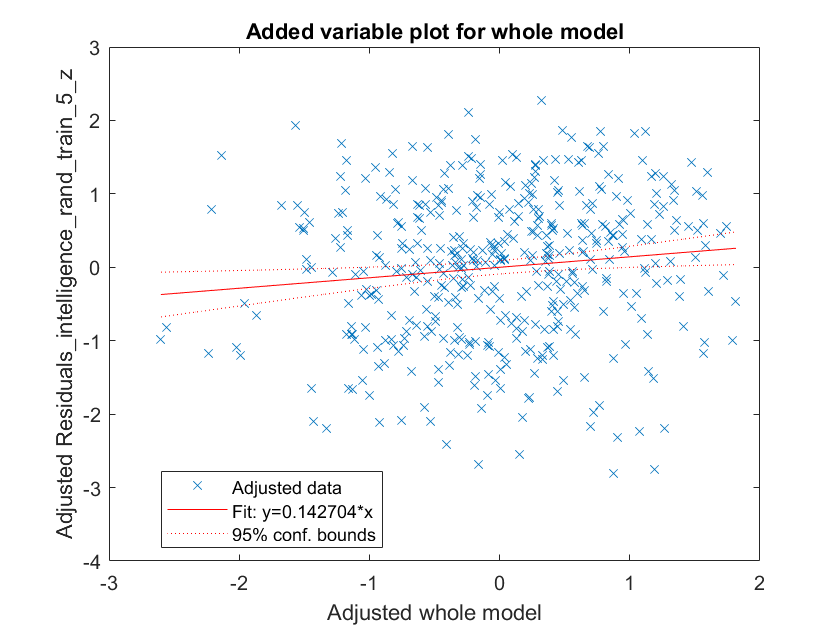

Model_Matrix = [residuals_pos_train_5 residuals_neg_train_5 residuals_intelligence_train_5_z_rand];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_5', 'residuals_neg_train_5','Residuals_intelligence_rand_train_5_z'};

mdl_pos_neg_bcs_train_5_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5_rand);

**2) Predict Intelligence in the Test Samples**

Test Sample 1 

Convert scores into z-scores

ALter_test_1_z = normalize(ALter_test_1);
Gender_test_1_z = normalize(Gender_test_1);
meanFDJenk_test_1_z = normalize(meanFDJenk_test_1);
LQ_test_1_z = normalize(LQ_test_1);

Intelligence_test_1_z = normalize(Intelligence_test_1);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [ALter_test_1_z Gender_test_1_z meanFDJenk_test_1_z LQ_test_1_z];
int_pred_test_1 = predict(mdl_regress_train_1_intelligence_rand,confounds);

residuals_intelligence_test_1_z = (Intelligence_test_1_z - int_pred_test_1);


Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{1,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_1_z Gender_test_1_z meanFDJenk_test_1_z LQ_test_1_z];


Positive_all_pred_test_1 = predict(mdl_regress_train_1_pos_bcs,confounds);

residuals_pos_test_1 = (Positive_all - Positive_all_pred_test_1);


Negative_all_pred_test_1 = predict(mdl_regress_train_1_neg_bcs,confounds);

residuals_neg_test_1 = (Negative_all - Negative_all_pred_test_1);

Xnew = [residuals_pos_test_1 residuals_neg_test_1];
ypred1_rand = predict(mdl_pos_neg_bcs_train_1_rand,Xnew);

[r,pval] = corr(ypred1_rand,residuals_intelligence_test_1_z);

Test Sample 2 

Convert scores into z-scores

ALter_test_2_z = normalize(ALter_test_2);
Gender_test_2_z = normalize(Gender_test_2);
meanFDJenk_test_2_z = normalize(meanFDJenk_test_2);
LQ_test_2_z = normalize(LQ_test_2);

Intelligence_test_2_z = normalize(Intelligence_test_2);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [ALter_test_2_z Gender_test_2_z meanFDJenk_test_2_z LQ_test_2_z];
int_pred_test_2 = predict(mdl_regress_train_2_intelligence_rand,confounds);

residuals_intelligence_test_2_z = (Intelligence_test_2_z - int_pred_test_2);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{2,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_2_z Gender_test_2_z meanFDJenk_test_2_z LQ_test_2_z];

Positive_all_pred_test_2 = predict(mdl_regress_train_2_pos_bcs,confounds);

residuals_pos_test_2 = (Positive_all - Positive_all_pred_test_2);

Negative_all_pred_test_2 = predict(mdl_regress_train_2_neg_bcs,confounds);

residuals_neg_test_2 = (Negative_all - Negative_all_pred_test_2);

Xnew = [residuals_pos_test_2 residuals_neg_test_2];
ypred2_rand = predict(mdl_pos_neg_bcs_train_2_rand,Xnew);

[r,pval] = corr(ypred2_rand,residuals_intelligence_test_2_z);

Test Sample 3 

Convert scores into z-scores

ALter_test_3_z = normalize(ALter_test_3);
Gender_test_3_z = normalize(Gender_test_3);
meanFDJenk_test_3_z = normalize(meanFDJenk_test_3);
LQ_test_3_z = normalize(LQ_test_3);

Intelligence_test_3_z = normalize(Intelligence_test_3);

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [ALter_test_3_z Gender_test_3_z meanFDJenk_test_3_z LQ_test_3_z];
int_pred_test_3 = predict(mdl_regress_train_3_intelligence_rand,confounds);

residuals_intelligence_test_3_z = (Intelligence_test_3_z - int_pred_test_3);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{3,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_3_z Gender_test_3_z meanFDJenk_test_3_z LQ_test_3_z];

Positive_all_pred_test_3 = predict(mdl_regress_train_3_pos_bcs,confounds);

residuals_pos_test_3 = (Positive_all - Positive_all_pred_test_3);

Negative_all_pred_test_3 = predict(mdl_regress_train_3_neg_bcs,confounds);

residuals_neg_test_3 = (Negative_all - Negative_all_pred_test_3);

Xnew = [residuals_pos_test_3 residuals_neg_test_3];
ypred3_rand = predict(mdl_pos_neg_bcs_train_3_rand,Xnew);


[r,pval] = corr(ypred3_rand,residuals_intelligence_test_3_z);

Test Sample 4 

Convert scores into z-scores

ALter_test_4_z = normalize(ALter_test_4);
Gender_test_4_z = normalize(Gender_test_4);
meanFDJenk_test_4_z = normalize(meanFDJenk_test_4);
LQ_test_4_z = normalize(LQ_test_4);

Intelligence_test_4_z = normalize(Intelligence_test_4);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [ALter_test_4_z Gender_test_4_z meanFDJenk_test_4_z LQ_test_4_z];
int_pred_test_4 = predict(mdl_regress_train_4_intelligence_rand,confounds);

residuals_intelligence_test_4_z = (Intelligence_test_4_z - int_pred_test_4);

Create the Averages for the People 

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{4,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_4_z Gender_test_4_z meanFDJenk_test_4_z LQ_test_4_z];

Positive_all_pred_test_4 = predict(mdl_regress_train_4_pos_bcs,confounds);

residuals_pos_test_4 = (Positive_all - Positive_all_pred_test_4);

Negative_all_pred_test_4 = predict(mdl_regress_train_4_neg_bcs,confounds);

residuals_neg_test_4 = (Negative_all - Negative_all_pred_test_4);

Xnew = [residuals_pos_test_4 residuals_neg_test_4];
ypred4_rand = predict(mdl_pos_neg_bcs_train_4_rand,Xnew);


[r,pval] = corr(ypred4_rand,residuals_intelligence_test_4_z);

Test Sample 5 

Convert scores into z-scores

ALter_test_5_z = normalize(ALter_test_5);
Gender_test_5_z = normalize(Gender_test_5);
meanFDJenk_test_5_z = normalize(meanFDJenk_test_5);
LQ_test_5_z = normalize(LQ_test_5);

Intelligence_test_5_z = normalize(Intelligence_test_5);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [ALter_test_5_z Gender_test_5_z meanFDJenk_test_5_z LQ_test_5_z];
int_pred_test_5 = predict(mdl_regress_train_5_intelligence_rand,confounds);

residuals_intelligence_test_5_z = (Intelligence_test_5_z - int_pred_test_5);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{5,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_5_z Gender_test_5_z meanFDJenk_test_5_z LQ_test_5_z];

Positive_all_pred_test_5 = predict(mdl_regress_train_5_pos_bcs,confounds);

residuals_pos_test_5 = (Positive_all - Positive_all_pred_test_5);

Negative_all_pred_test_5 = predict(mdl_regress_train_5_neg_bcs,confounds);

residuals_neg_test_5 = (Negative_all - Negative_all_pred_test_5);

Xnew = [residuals_pos_test_5 residuals_neg_test_5];
ypred5_rand = predict(mdl_pos_neg_bcs_train_5_rand,Xnew);

[r,pval] = corr(ypred5_rand,residuals_intelligence_test_5_z);

**3) Correlate the predicted scores with the actual scores**

predicted_scores = [ypred1_rand; ypred2_rand; ypred3_rand; ypred4_rand; ypred5_rand];
actual_scores = [residuals_intelligence_test_1_z; residuals_intelligence_test_2_z; residuals_intelligence_test_3_z; residuals_intelligence_test_4_z; residuals_intelligence_test_5_z];

[rho_final,pval_final] = corr(predicted_scores,actual_scores);

**4) Save rho_final & pval_final for Permutation Test **

Permutation_test_all_cross_val_rounds_rho_AOMIC{cross_validation_round,permutation_test_round} = rho_final;
Permutation_test_all_cross_val_rounds_pval_AOMIC{cross_validation_round, permutation_test_round} = pval_final;

**End permutation test **

end

end

## **4. Analysis Section**

all_rhos_final_correlations = cell2mat(cross_validation_100_final_correlation_AOMIC(:,1))

all_rhos_final_correlations =     0.1620
    0.1965
    0.1640
    0.1717
    0.1480
    0.1654
    0.1634
    0.1678
    0.1766
    0.1837



mean_all_rhos_final_correlations = mean(all_rhos_final_correlations)

mean_all_rhos_final_correlations = 0.1664


Permutation_test_all_cross_val_rounds_rho_mat = cell2mat(Permutation_test_all_cross_val_rounds_rho_AOMIC)

Permutation_test_all_cross_val_rounds_rho_mat =    -0.0347   -0.0618    0.0263    0.1254    0.1047   -0.1605   -0.0511   -0.0809   -0.0467   -0.0745
   -0.0661    0.0031    0.0536   -0.0322   -0.0876    0.0011    0.0274   -0.1535    0.0307    0.0179
   -0.0894    0.0789    0.1153    0.0061    0.0792    0.1382   -0.0294   -0.1518   -0.0036   -0.0416
    0.1100   -0.0582   -0.0953    0.1320    0.0665    0.1117    0.0727   -0.0250    0.1125    0.0140
   -0.0739    0.0779   -0.0214   -0.0280    0.0652   -0.0298   -0.0396   -0.1382   -0.0386   -0.0248
   -0.0693    0.0474    0.1264    0.0377   -0.0341   -0.0237   -0.0781   -0.0393    0.0005   -0.1506
   -0.0576    0.0504    0.0099   -0.0347   -0.0140    0.0716   -0.0524    0.0031    0.0577    0.0657
   -0.0510   -0.0338    0.1237    0.0535    0.0190   -0.0131    0.0473    0.0747   -0.0385    0.0195
    0.0960    0.0223    0.0719    0.0028    0.0202   -0.0264    0.0424   -0.1082   -0.0023   -0.0075
   -0.0037    0.1047    0.0138    0.0331   



find(Permutation_test_all_cross_val_rounds_rho_mat > mean_all_rhos_final_correlations)

ans =    152
   353
